# Robotics 2 - Final exam, February 5, 2018

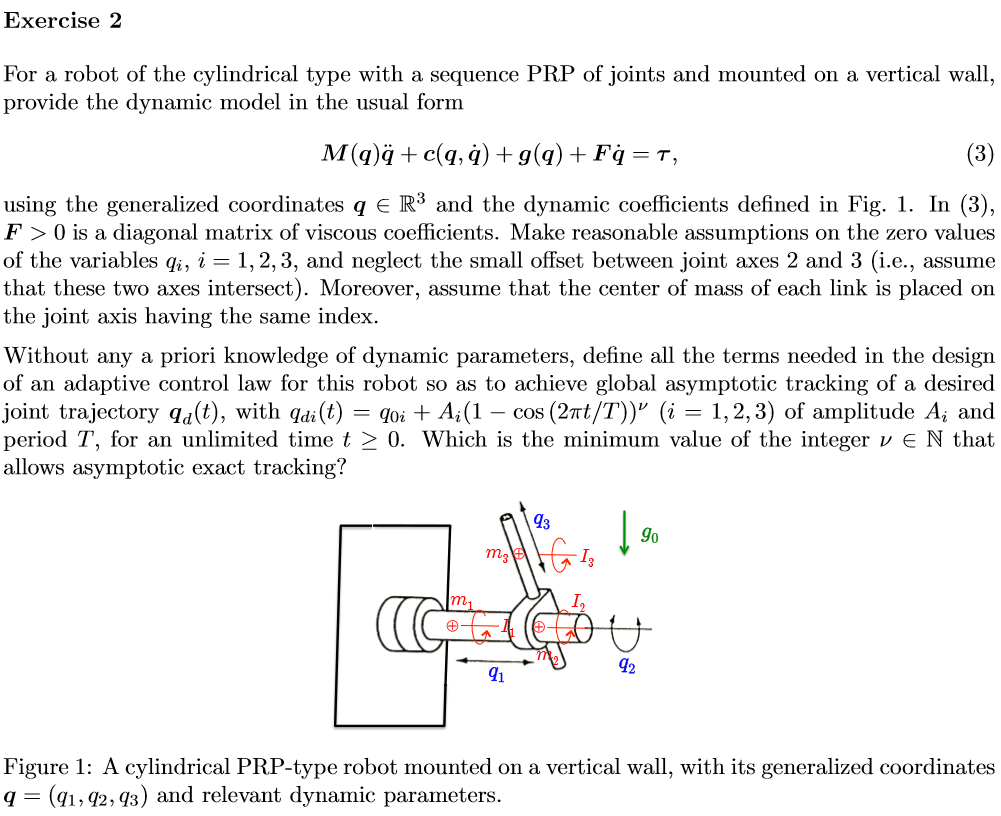

clear; clc;
sigma = [1,0,1]; %PRP
n= length(sigma)

n = 3

q = sym('q',[n 1]);
qd = sym('qd',[n 1]);
qdd = sym('qdd',[n 1]);
l = sym('l',[n 1]);
m = sym('m',[n 1]);
d = sym('d',[n 1]);
I = sym('I',[n 1]);
g = sym('g')

$$g = g$$

g0 = [0 g 0].'

$$g0 = \left(\begin{array}{c} 0\\ g\\ 0 \end{array}\right)$$

F = diag(sym('f',[n,1]));
dhTable = [0    0 q(1) 0;
           -pi/2 0 0 q(2);
           0 0 q(3)-d(3) 0]

$$dhTable = \left(\begin{array}{cccc} 0 & 0 & q_{1} & 0\\ -\frac{\pi }{2} & 0 & 0 & q_{2}\\ 0 & 0 & q_{3}-d_{3} & 0 \end{array}\right)$$

%l = [q(1) 0 q(3)]
%dc = [q(1) - di(1), di(2), q(3)-di(3)]

[KE, T] = getKEwithJacobian(dhTable,sigma,q,qd,l,m,I,d,0)

*** Computation of Kinetic Energy (Jacobian-based method) 


$$KE = \frac{I_{2}\,{{\mathrm{qd}}_{2}}^{2}}{2}+\frac{I_{3}\,{{\mathrm{qd}}_{2}}^{2}}{2}+\frac{m_{1}\,{{\mathrm{qd}}_{1}}^{2}}{2}+\frac{m_{2}\,{{\mathrm{qd}}_{1}}^{2}}{2}+\frac{m_{3}\,{{\mathrm{qd}}_{1}}^{2}}{2}+\frac{m_{3}\,{{\mathrm{qd}}_{3}}^{2}}{2}+\frac{{d_{3}}^{2}\,m_{3}\,{{\mathrm{qd}}_{2}}^{2}}{2}+\frac{m_{3}\,{q_{3}}^{2}\,{{\mathrm{qd}}_{2}}^{2}}{2}-d_{3}\,m_{3}\,q_{3}\,{{\mathrm{qd}}_{2}}^{2}$$

T = 1×3 cell array
    {1×1 sym}    {1×1 sym}    {1×1 sym}


for i=1:n
    T{i}
end

$$ans = \frac{m_{1}\,{{\mathrm{qd}}_{1}}^{2}}{2}$$

$$ans = \frac{m_{2}\,{{\mathrm{qd}}_{1}}^{2}}{2}+\frac{I_{2}\,{{\mathrm{qd}}_{2}}^{2}}{2}$$

$$ans = \frac{m_{3}\,{d_{3}}^{2}\,{{\mathrm{qd}}_{2}}^{2}}{2}-m_{3}\,d_{3}\,q_{3}\,{{\mathrm{qd}}_{2}}^{2}+\frac{m_{3}\,{q_{3}}^{2}\,{{\mathrm{qd}}_{2}}^{2}}{2}+\frac{m_{3}\,{{\mathrm{qd}}_{1}}^{2}}{2}+\frac{I_{3}\,{{\mathrm{qd}}_{2}}^{2}}{2}+\frac{m_{3}\,{{\mathrm{qd}}_{3}}^{2}}{2}$$

M = getInertiaMatrixFromKE(KE,qd)

$$M = \left(\begin{array}{ccc} m_{1}+m_{2}+m_{3} & 0 & 0\\ 0 & m_{3}\,{d_{3}}^{2}-2\,m_{3}\,d_{3}\,q_{3}+m_{3}\,{q_{3}}^{2}+I_{2}+I_{3} & 0\\ 0 & 0 & m_{3} \end{array}\right)$$

[C,cac,Csubs,S] = getCs(M,q,qd)

>> Getting  the Christoffel’sym. Might take a while...


C = 1×3 cell array
    {3×3 sym}    {3×3 sym}    {3×3 sym}


$$cac = \left(\begin{array}{c} 0\\ \frac{m_{3}\,\left({q_{3}}^{2}\,{{\mathrm{qd}}_{3}}^{2}\,{\left|{\mathrm{qd}}_{2}\right|}^{2}-d_{3}\,q_{3}\,{{\mathrm{qd}}_{2}}^{2}\,{\left|{\mathrm{qd}}_{3}\right|}^{2}-d_{3}\,q_{3}\,{{\mathrm{qd}}_{3}}^{2}\,{\left|{\mathrm{qd}}_{2}\right|}^{2}+{{\mathrm{qd}}_{2}}^{2}\,{\left|q_{3}\right|}^{2}\,{\left|{\mathrm{qd}}_{3}\right|}^{2}\right)}{q_{3}\,{\mathrm{qd}}_{2}\,{\mathrm{qd}}_{3}}\\ m_{3}\,{\left|{\mathrm{qd}}_{2}\right|}^{2}\,\left(d_{3}-q_{3}\right) \end{array}\right)$$

Csubs = 1×3 cell array
    {3×3 sym}    {3×3 sym}    {3×3 sym}


$$S = \left(\begin{array}{ccc} 0 & 0 & 0\\ 0 & -m_{3}\,\bar{{\mathrm{qd}}_{3}}\,\left(d_{3}-\bar{q_{3}}\right) & -m_{3}\,\bar{{\mathrm{qd}}_{2}}\,\left(d_{3}-q_{3}\right)\\ 0 & m_{3}\,\bar{{\mathrm{qd}}_{2}}\,\left(d_{3}-q_{3}\right) & 0 \end{array}\right)$$

g_q = getGravityWithJacobian(dhTable,q,l,m,d,g0,0)

*** Computation of Potential Energy (Jacobian-based method) 


$$g\_q = \left(\begin{array}{c} 0\\ g\,m_{3}\,\sin\left(q_{2}\right)\,\left(d_{3}-q_{3}\right)\\ g\,m_{3}\,\cos\left(q_{2}\right) \end{array}\right)$$

torque = M*qdd + C + g_q +F*qd

$$torque = \begin{array}{l} \left(\begin{array}{ccccccccc} \sigma_{2} & \sigma_{2} & \sigma_{2} & \sigma_{2} & \sigma_{2} & \sigma_{2} & \sigma_{2} & \sigma_{2} & \sigma_{2}\\ \sigma_{3} & \sigma_{3} & \sigma_{3} & \sigma_{3} & \sigma_{3} & f_{2}\,{\mathrm{qd}}_{2}-m_{3}\,\left(d_{3}-q_{3}\right)+\sigma_{4}+\sigma_{5} & \sigma_{3} & f_{2}\,{\mathrm{qd}}_{2}+m_{3}\,\left(d_{3}-q_{3}\right)+\sigma_{4}+\sigma_{5} & \sigma_{3}\\ \sigma_{1} & \sigma_{1} & \sigma_{1} & \sigma_{1} & f_{3}\,{\mathrm{qd}}_{3}+m_{3}\,{\mathrm{qdd}}_{3}-m_{3}\,\left(d_{3}-\bar{q_{3}}\right)+g\,m_{3}\,\cos\left(q_{2}\right) & \sigma_{1} & \sigma_{1} & \sigma_{1} & \sigma_{1} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=f_{3}\,{\mathrm{qd}}_{3}+m_{3}\,{\mathrm{qdd}}_{3}+g\,m_{3}\,\cos\left(q_{2}\right)\\ \sigma_{2}=f_{1}\,{\mathrm{qd}}_{1}+{\mathrm{qdd}}_{1}\,\left(m_{1}+m_{2}+m_{3}\right)\\ \sigma_{3}=f_{2}\,{\mathrm{qd}}_{2}+\sigma_{4}+\sigma_{5}\\ \sigma_{4}={\mathrm{qdd}}_{2}\,\left(m_{3}\,{d_{3}}^{2}-2\,m_{3}\,d_{3}\,q_{3}+m_{3}\,{q_{3}}^{2}+I_{2}+I_{3}\right)\\ \sigma_{5}=g\,m_{3}\,\sin\left(q_{2}\right)\,\left(d_{3}-q_{3}\right) \end{array}$$

[All, dynamicParamsReturn, a]= getDynamicParameters([M,(S),diag(g_q),F],q,[qd.',g],2)

Unrecognized function or variable 'F'.

[M,S,diag(g_q),F]
a_order = a([1,7,2,5,3,4,6])

Msubs = All(:,1:3)
Ssubs = All(:,4:6)
gSubs = diag(All(:,7:9))
FSubs = All(:,10:12)

torqueSubs = Msubs*qdd + Ssubs*qd + gSubs +FSubs*qd

getLinearParametrization(torqueSubs,a_order)